**NOTA, SE S NON è SKEW-SYMMETRIC LA FATTORIZZAZIONE NON PUò ESSERE SKEW SYMMETRIC**

**In questo script calcoliamo solo la fattorizzazione dei velocity tems:**

- **si assume c gia calcolato **

Se vieni dal codice per calcolare **c (velocity tems) ** non devi definire niente, altrimenti se vuoi inserire una particolare forma per i velocity terms lo facciamo qui 

% syms q1 q2 qd1 qd2 a2 a3 real;
% n=2;
% q=[q1;q2];
% qd=[qd1;qd2];
% c=[qd1*qd2*sin(2*q2)*(a2-a3);-(1/2)*qd1^2*sin(2*q2)*(a2-a3)]

i velocity term sono uguali a:

c

$$c = \left(\begin{array}{c} -{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)\\ \frac{{{\mathrm{qd}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} \end{array}\right)$$

**Dati i velocity terms we want to find o factorizations of the associated Coriolis/centrifugal terms **$c(q,\dot{q})=S'(q,\dot{q})\dot{q}=S''(q,\dot{q})\dot{q}$** such that the matrix **$\dot{M}-2S'$** is skew symmetric, while the matrix **$\dot{M}-2S''$** is not.**

**The factorization  **$c(q,\dot{q})=S'(q,\dot{q})\dot{q}$** such that the matrix **$\dot{M}-2S'$** is skew symmetric is simple given:**

- **  (when we have the Cristoffel Symbols **$C_i$ (the matrices)**) by **

                $S'(q,\dot{q})=(\dot{q}^T C_1(q) \quad \dot{q}^T C_2(q))^T$** , and we have that  **$c(q,\dot{q})=S'(q,\dot{q})\dot{q}$** :**

S1=[transpose(qd)*C(:,:,1);transpose(qd)*C(:,:,2)]

$$S1 = \left(\begin{array}{cc} -\frac{{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} & -\frac{{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2}\\ \frac{{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} & 0 \end{array}\right)$$

%S1=[transpose(qd)*C(:,:,1);transpose(qd)*C(:,:,2);transpose(qd)*C(:,:,3)]
%S1=[transpose(qd)*C(:,:,1);transpose(qd)*C(:,:,2);transpose(qd)*C(:,:,3);transpose(qd)*C(:,:,4)]

- **Oppure in alternativa se non ho i Cristoffel's symbols ma solo i velocity terms, posso ottenre la stessa identica fattorizzazione utilizzando:**

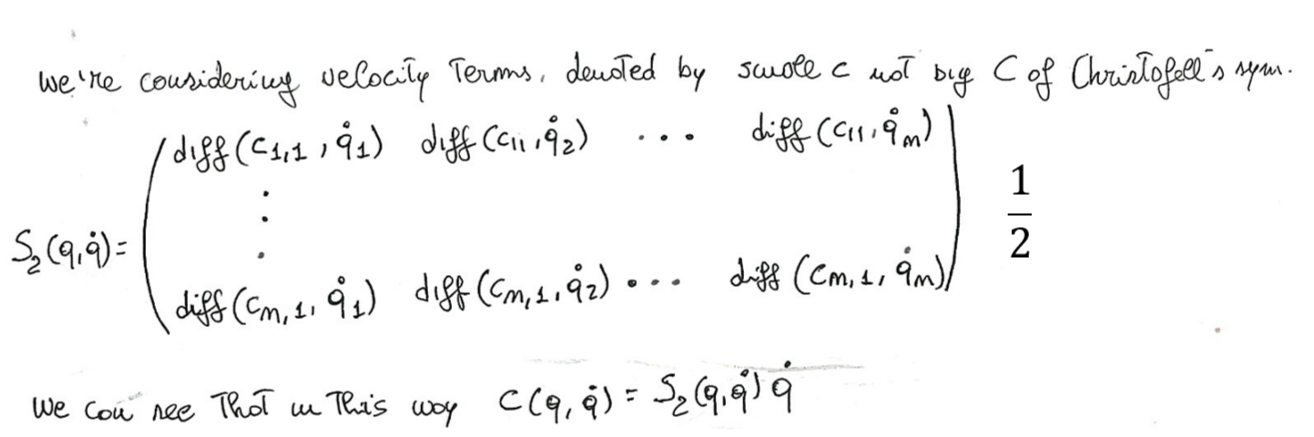

for i=1:n
    for j=1:n
        S11(i,j)=1/2*diff(c(i,1),qd(j,1));
    end
end 
S11

$$S11 = \left(\begin{array}{cc} -\frac{{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} & -\frac{{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2}\\ \frac{{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} & 0 \end{array}\right)$$

La dimostrazione segue. E' da verificare solamente il parametro $\frac{1}{2}$ che forse potrebbe essere $\frac{1}{n}$ ma non credo proprio vista la dimostrazione.(Alla fine della pagina)

CONTROLLO SE LE MATRICI $\dot{M}-2S$ sono skew symmetric o meno

%se non hai ricavato gia Definito M definiscila ora
%syms a1 a2 a3 a4 real;
%M=[a1+a2*sin(q2)^2+a3*cos(q2)^2 0; 0 a4]  

%dobbiamo derivare M rispetto al tempo, quindi:
Mdot=diff(M,q(1,1))*qd(1,1);
for i=2:n
    Mdot=simplify(Mdot+diff(M,q(i,1))*qd(i,1));
end
Mdot

$$Mdot = \left(\begin{array}{cc} -{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right) & 0\\ 0 & 0 \end{array}\right)$$

Verifrichiamo se le matrici $\dot{M}-2S$ ottenute sono Skew-Symmetric o meno, questo si vede considerando il fatto che per una matrice *S(q)* Skew-symmetric vale la proprietà $S(q)^T=-S(q)$

firstMat=simplify(Mdot-2*S1)

$$firstMat = \left(\begin{array}{cc} 0 & {\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)\\ -{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right) & 0 \end{array}\right)$$

%fisrtMat=Mdot-2*S11
if(transpose(firstMat)==-firstMat)
    disp(' YES,the "fisrtmat" is Skew-Symmetric')
else
    disp('NO;the "fisrtmat" is NOT Skew-Symmetric')
end

 YES,the "fisrtmat" is Skew-Symmetric


una fattorizzazione $c(q,\dot{q})=S''(q,\dot{q})\dot{q}$** such that the matrix **$\dot{M}-2S'$** is NOT skew symmetric B, **è data da qualunque fattorizzazione che non sia diagonale e che segua la forma:

**E' sempre meglio provare a farla a mano prima**

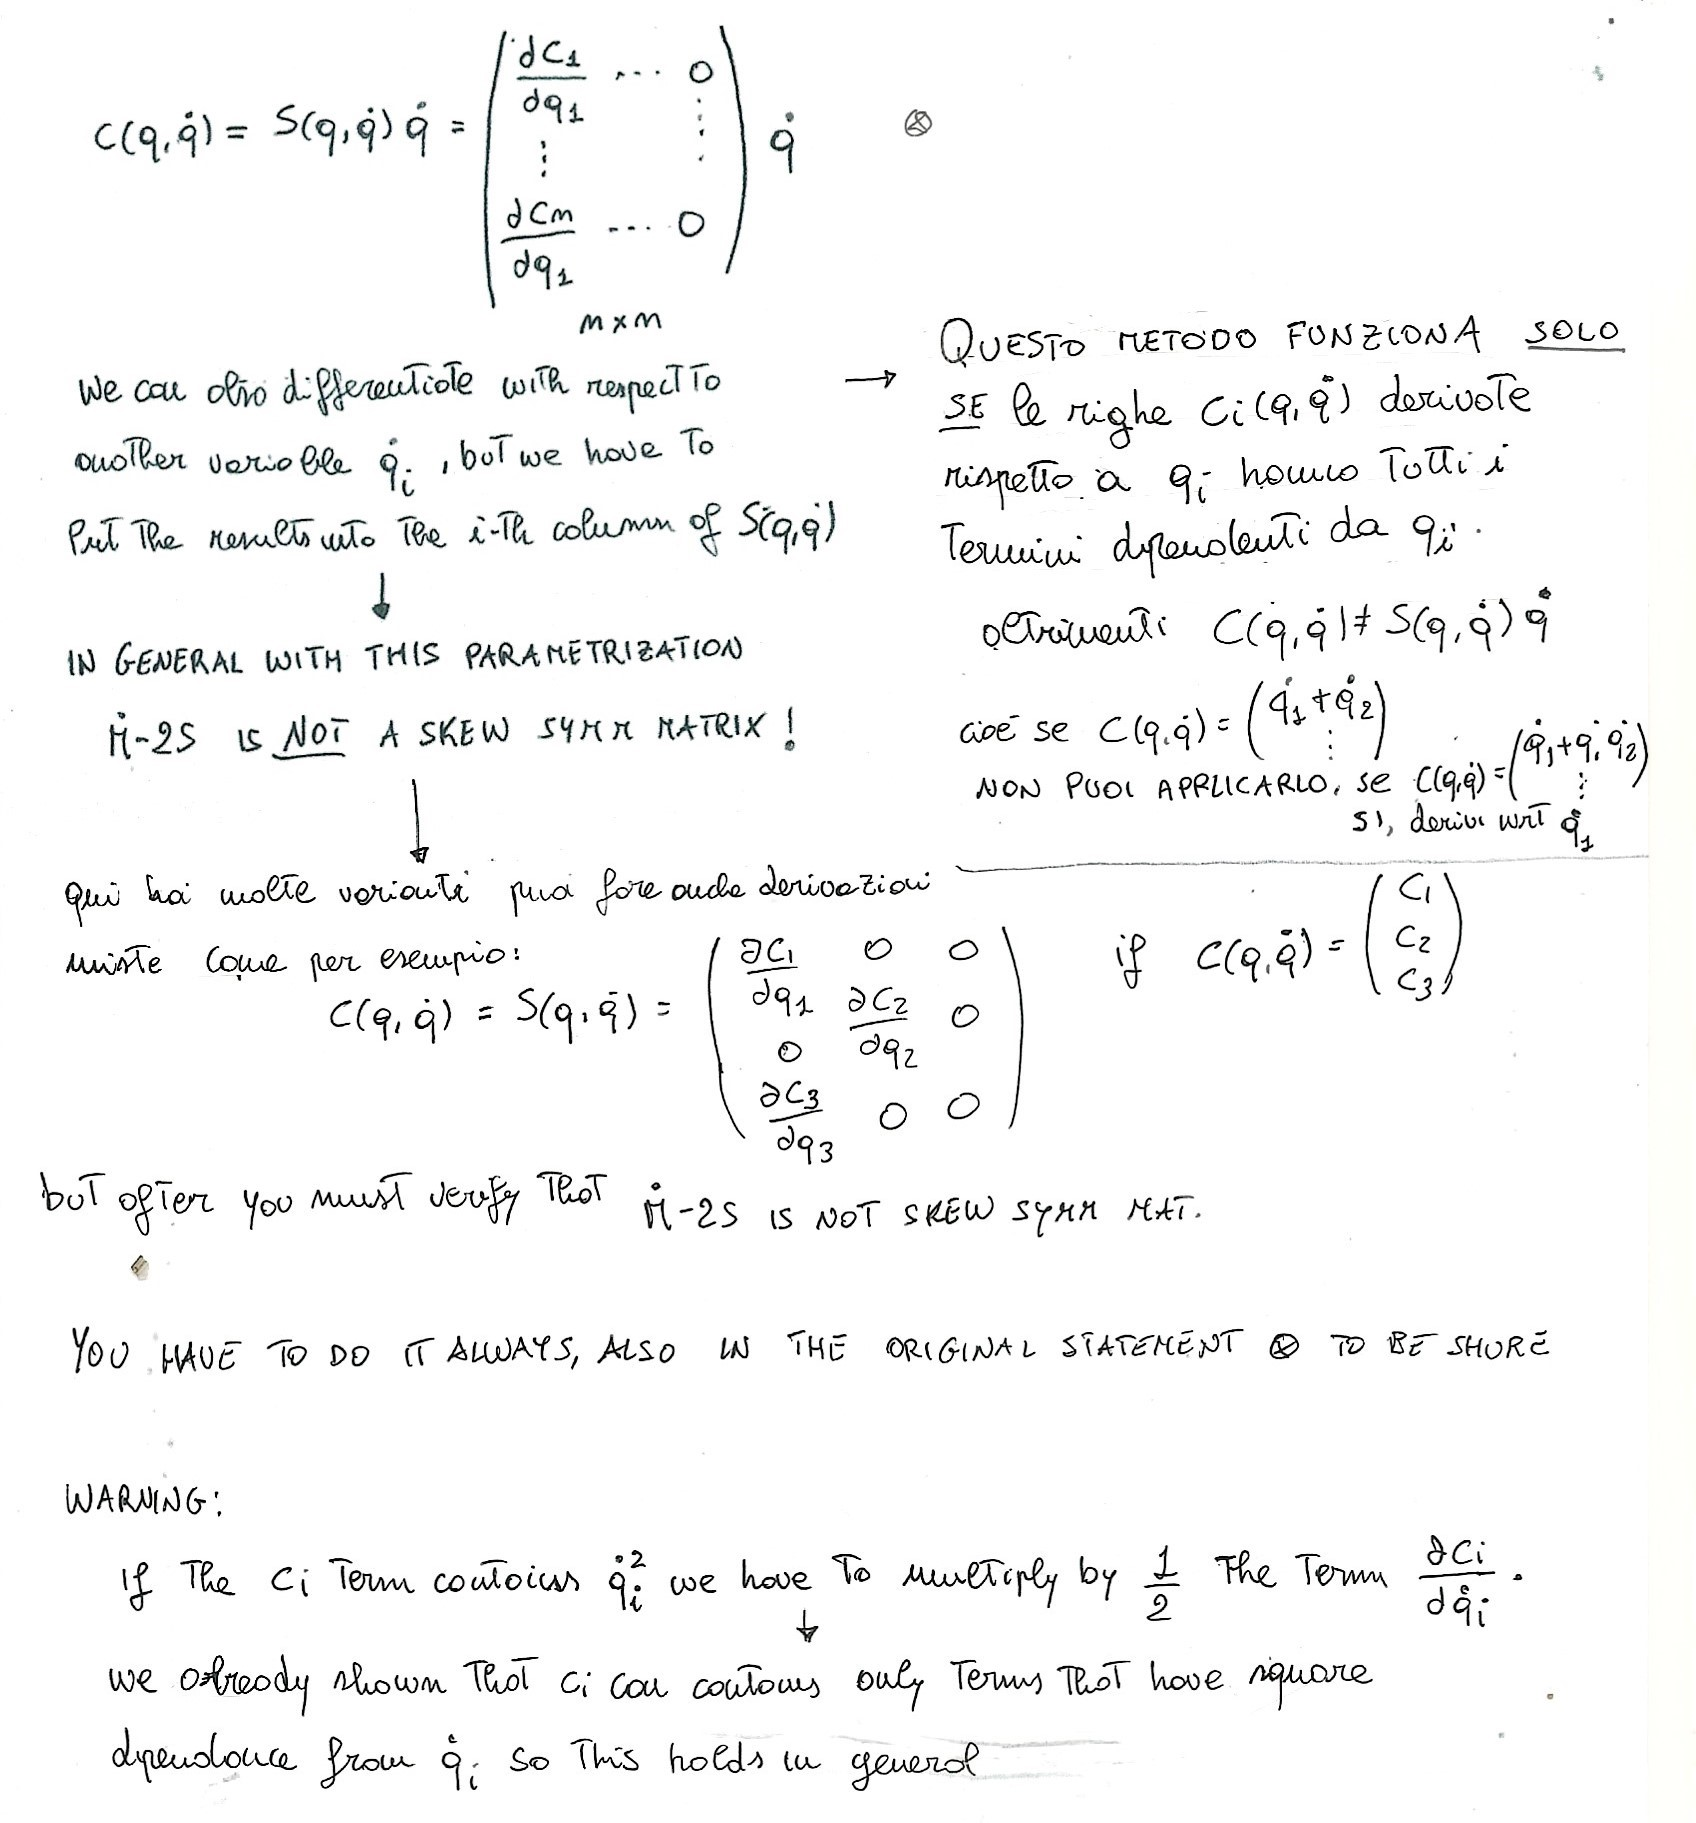

colonna_da_considerare=ones(n,1); % ma ricordati qui puoi fare tutte le derivate che vuoi basta che poi verifichi che la fatorizzazione sia corretta
%considero le derivate parziali rispetto qd2

%colonna_da_considerare=[1;2]

%se [1;1] significa che derivi c1 e c2 ripsetto qd1 e qd2
%se [1;2] significa che derivi c1 ripsetto qd1 e c2 rispetto qd2


if(size(colonna_da_considerare)~=n)
    error('il vettore colonna_da_considerare ha dimensioni sbagliate')
end

S2=sym('S2',[n,n]);

for i=1:n
    factor=1;
    sym_vars=symvar(c(i,1));
    if(ismember(qd(colonna_da_considerare(i,1),1),sym_vars))
        sym_vars=symvar( diff(c(i,1),qd(colonna_da_considerare(i,1),1)) );
        if(ismember(qd(colonna_da_considerare(i,1),1),sym_vars))
            factor=1/2;
        end
    end
    
%è abbastanza solito che dia errore procedi a mano tanto devi trovare una
%fattorizzazione non skew symmetric qui 
    for j=1:n
        if(j==colonna_da_considerare)
            S2(i,j)=factor*diff(c(i,1),qd(j,1));
        else
            S2(i,j)=0;
        end
    end
end 
S2

$$S2 = \left(\begin{array}{cc} -{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right) & 0\\ \frac{{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} & 0 \end{array}\right)$$

c

$$c = \left(\begin{array}{c} -{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)\\ \frac{{{\mathrm{qd}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right)}{2} \end{array}\right)$$



if(S2*qd==c)
    disp('Correct factorization')
else
    error('The factorization is NOT CORRECT , devi cambiare colonne da considerare ')
end

Correct factorization


SecondMat=Mdot-2*S2

$$SecondMat = \left(\begin{array}{cc} {\mathrm{qd}}_{2}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right) & 0\\ -{\mathrm{qd}}_{1}\,\sin\left(2\,q_{2}\right)\,\left(a_{2}-a_{3}+a_{4}\right) & 0 \end{array}\right)$$

if(transpose(SecondMat)==-SecondMat)
    disp(' YES,the "SecondMat" is Skew-Symmetric')
else
    disp('NO;the "SecondMat" is NOT Skew-Symmetric')
end

NO;the "SecondMat" is NOT Skew-Symmetric


Dimostrazione di cui si parlava